clear all
Data =readtable("ElectricityPrices2022.csv");

DaysWanted = 120;
Data= Data(1:(24*DaysWanted),:);

DKKtoEUR = 0.13; 

%The values are based on a B-Low customer during winter.
BaseLoadRate = 0.0666*DKKtoEUR*1000; %In EUR/MWh
HighLoadRate = 0.1998*DKKtoEUR*1000; %In EUR/MWh
PeakLoadRate = 0.3996*DKKtoEUR*1000; %In EUR/MWh

for i =1:height(Data)
    HighLoadPeriod=false;
    PeakLoadPeriod=false;
    for j=[6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
        if(hour(Data.StartTime(i))==j)
            Data.NewPrice(i)= Data.Price(i) + PeakLoadRate;

            if isweekend(Data.EndTime) == 0
                PeakLoadPeriod=true;
            elseif isweekend(Data.EndTime) == 1
                HighLoadPeriod = true;
            end            
        end
    end
    for j=[21 22 23]
        if(hour(Data.StartTime(i))==j)
            Data.NewPrice(i)= Data.Price(i) + HighLoadRate ;
            HighLoadPeriod=true;
        end
    end  
    if(PeakLoadPeriod==false && HighLoadPeriod==false)
        Data.NewPrice(i) = Data.Price(i) + BaseLoadRate;
    end
end

A = Data.NewPrice;

save("ElPrice.mat" , 'A')

## Making a plot for the report:

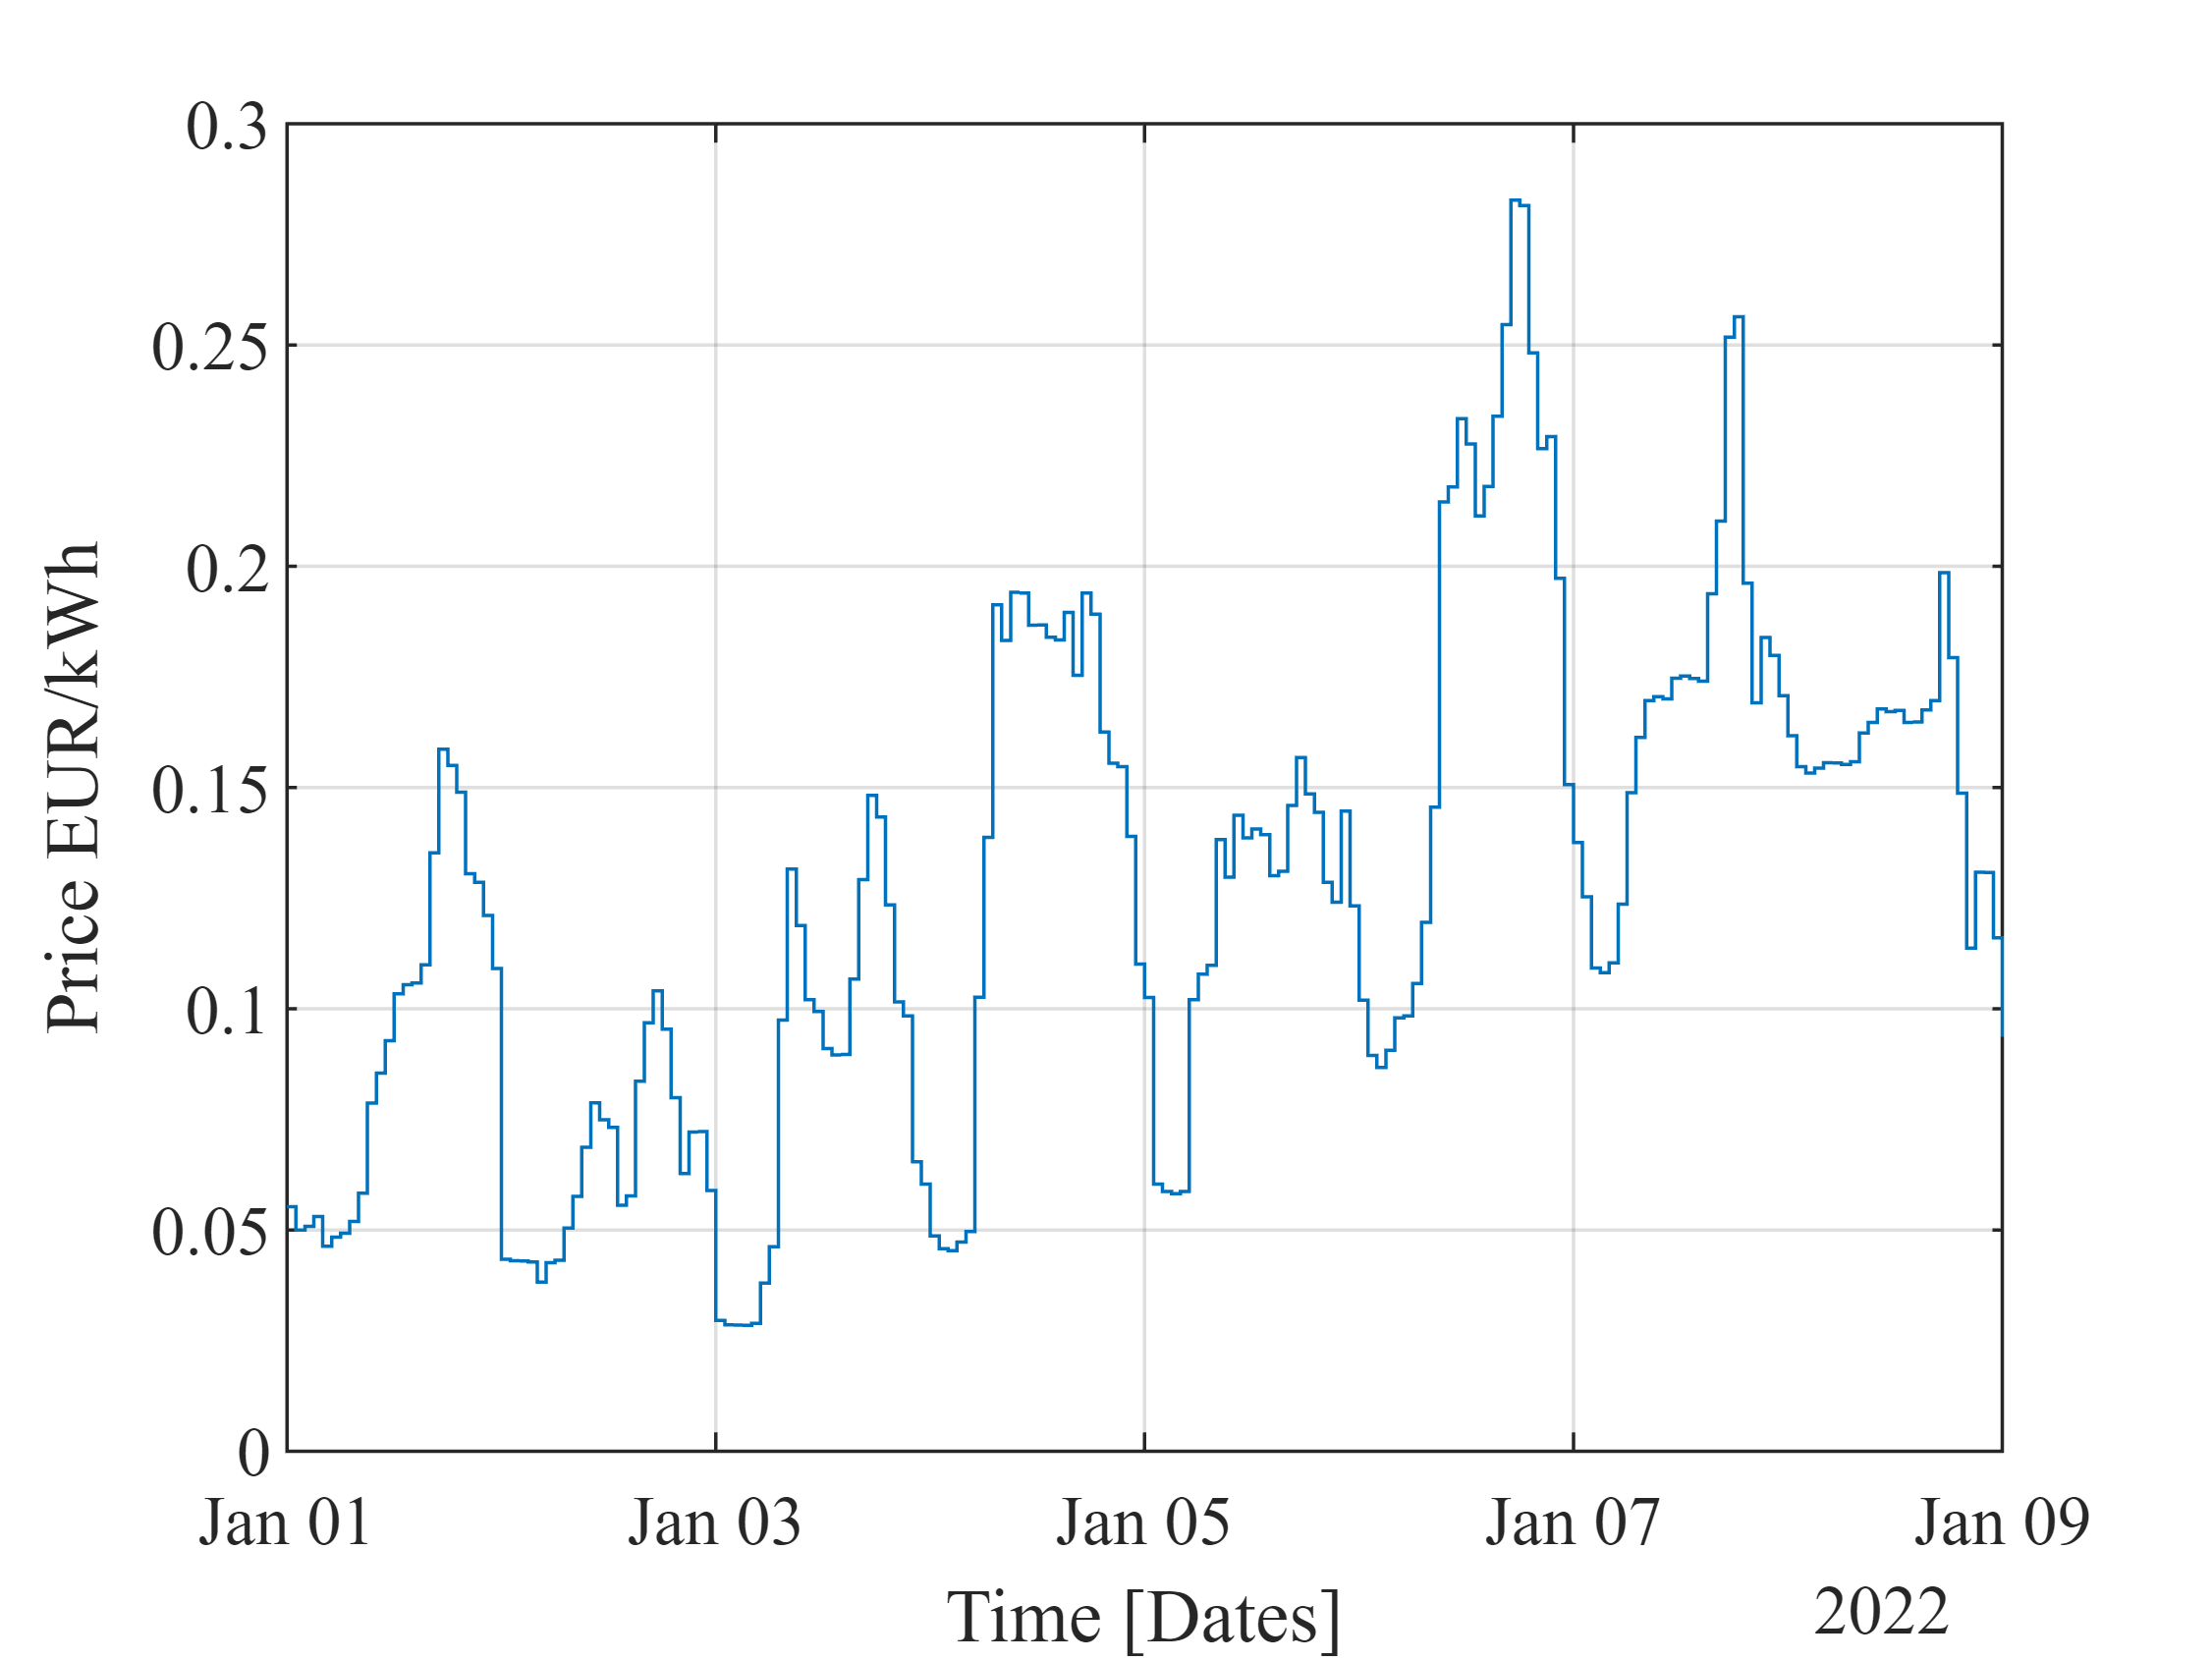

f=figure;
set(0, 'DefaultAxesFontName', 'Times');
set(0, 'DefaultLegendFontName', 'Times');

stairs(Data.StartTime(1:193,1), Data.NewPrice(1:193,1)/1000)
xlabel("Time [Dates]")
ylabel("Price EUR/kWh")
grid on 

exportgraphics(f,'eletricityPrice.pdf')